**GRF Analysis**

The goal of this script is to analysis the relationship between 

addpath('../traj_opt_grf/');

human_model = '../human_8/';
humanExo_model= '../human_exo1/';

step1.human.base = load([human_model,'1209153338.mat']).result;
step1.human.hip = load([human_model,'1209152502.mat']).result;
step1.human.kne = load([human_model,'1209153428.mat']).result;
step1.human.ank = load([human_model,'1209153530.mat']).result;
step1.human.Hk = load([human_model,'1209153416.mat']).result;
step1.human.Ha = load([human_model,'1209154508.mat']).result;
step1.human.Ka = load([human_model,'1209155230.mat']).result;

step1.exo.base = load([humanExo_model,'1228144025.mat']).result;
step1.exo.hip = load([humanExo_model,'1228145354.mat']).result;
step1.exo.kne = load([humanExo_model,'1228144625.mat']).result;
step1.exo.ank = load([humanExo_model,'1228144620.mat']).result;
step1.exo.Hk = load([humanExo_model,'1228145444.mat']).result;
step1.exo.Ha = load([humanExo_model,'1228145121.mat']).result;
step1.exo.Ka = load([humanExo_model,'1228144534.mat']).result;

step2.human.base = load([human_model,'0103201326.mat']).result;
step2.human.hip = load([human_model,'0103201758.mat']).result;
step2.human.kne = load([human_model,'0103202640.mat']).result;
step2.human.ank = load([human_model,'0103202622.mat']).result;
step2.human.Hk = load([human_model,'0103201646.mat']).result;
step2.human.Ha = load([human_model,'0103202452.mat']).result;
step2.human.Ka = load([human_model,'0103202509.mat']).result;

step2.exo.base = load([humanExo_model,'0103211954.mat']).result;
step2.exo.hip = load([humanExo_model,'0103210819.mat']).result;
step2.exo.kne = load([humanExo_model,'0103210918.mat']).result;
step2.exo.ank = load([humanExo_model,'0103212720.mat']).result;
step2.exo.Hk = load([humanExo_model,'0103210655.mat']).result;
step2.exo.Ha = load([humanExo_model,'0103210640.mat']).result;
step2.exo.Ka = load([humanExo_model,'0103212827.mat']).result;



grf1 = biped_grf(step1.human.base.x,step1.human.base.param,human_model);
vel1 = biped_hipVel(step1.human.base.x,step1.human.base.param,human_model);
grf2 = biped_grf(step1.human.hip.x,step1.human.hip.param,human_model);
vel2 = biped_hipVel(step1.human.hip.x,step1.human.hip.param,human_model);

grf3 = biped_grf(step1.human.base.x,step1.human.base.param,human_model);
vel3 = biped_hipVel(step1.human.base.x,step1.human.base.param,human_model);
grf4 = biped_grf(step1.human.hip.x,step1.human.hip.param,human_model);
vel4 = biped_hipVel(step1.human.hip.x,step1.human.hip.param,human_model);

grf5 = biped_grf(step2.human.base.x,step2.human.base.param,human_model);
vel5 = biped_hipVel(step2.human.base.x,step2.human.base.param,human_model);
grf6 = biped_grf(step2.human.hip.x,step2.human.hip.param,human_model);
vel6 = biped_hipVel(step2.human.hip.x,step2.human.hip.param,human_model);


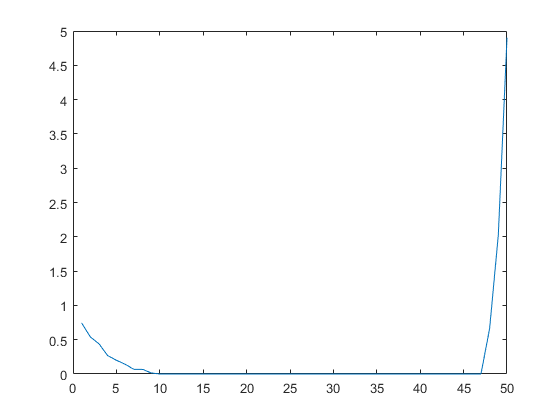

plot((grf1(4,:)+grf1(2,:))/75);

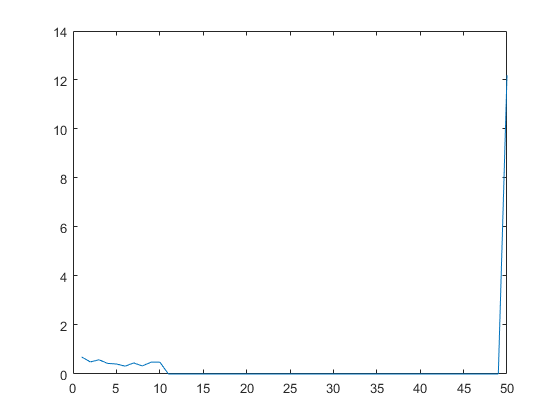

plot((grf5(4,:)+grf5(2,:))/75);